# Monte Carlo simulation of the Brownian bridge

dX = (b-X)/(T-t)*dt + sigma*dW

## Define parameters and time grid

clear all % clear all variables from memory
close all 
npaths = 20000; % number of paths
T = 1; % time horizon
nsteps = 200; % number of time steps
dt = T/nsteps; % time step
t = 0:dt:T; % observation times
sigma = 0.3; % volatility
a = 0.8; % initial value
b = 1; % final value

## Monte Carlo method 1

Possible roundoff and discritization aerro on final value! (maybe verify this)

BB: in point a (=start) is a dirac delta distribution, this is also the case for point 'b'

%Allocate and initialise all paths
X = [a*ones(1,npaths); zeros(nsteps-1,npaths); b*ones(1,npaths)];

% Compute the Brownian bridge with Euler-Maruyama
for i = 1:nsteps-1
     X(i+1,:) = X(i,:) + (b-X(i,:))/(nsteps-i+1) + sigma*randn(1,npaths)*sqrt(dt);
end

## Monte Carlo method 2

Compute the increments of driftless arithmetic Brownian motion (driftless ABM)

%dW = sigma*randn(nsteps,npaths)*sqrt(dt);


Accumulate the increments of arithmetic Brownian motion

Note that we start from 'a' => very similar to ABM code

%W = cumsum([a*ones(1,npaths); dW]);

Cumsum needs to be outside the brackets since we start from 'a'. this is not the case for abm, since it is starting from 0. Hence, cumsum can be inside the brackets too. 


% Compute the Brownian bridge with X(t) = W(t) + (b-W(T))/T*t
%X = W + repmat(b-W(end,:),nsteps+1,1)/T.*repmat(t',1,npaths);

**the previous line is a correction factor (you can prove this algebraically, nov22)**

**BB could be extended to everything dione as in OU (check ballota for the mmoments), conditions are fullfilled to express the anamytical moments. **

**=> analytical expr for mean and variance**

**=> autocov and plot against theo val?? (not strictly stationary, but there is an analytical expression)**

**=> analytical expr for the histograms to compare with?? Yes, it is an Gauss process, expressed in ballota**

## Expected, mean and sample paths 

(add the statistics)

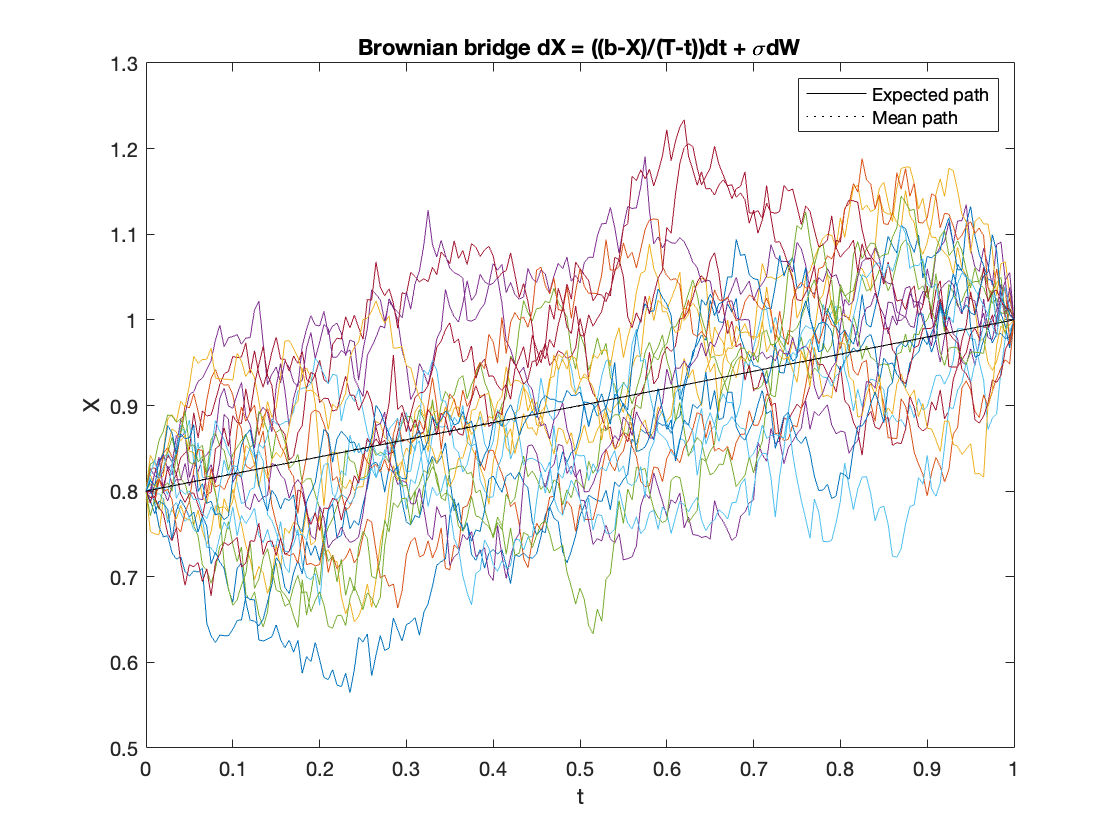

figure(1)
close all
EX = a + (b-a)/T*t; % expected path
plot(t,EX,'k',t,mean(X,2),':k',t,X(:,1:1000:end),t,EX,'k',t,mean(X,2),':k')
legend('Expected path','Mean path')
xlabel('t')
ylabel('X')
%sdevmax = sigma*sqrt(T)/2;
%ylim([(a+b)/2-4*sdevmax (a+b)/2+4*sdevmax])
title('Brownian bridge dX = ((b-X)/(T-t))dt + \sigmadW')
print('-dpng','bbpaths.png')

## Variance = mean square deviation

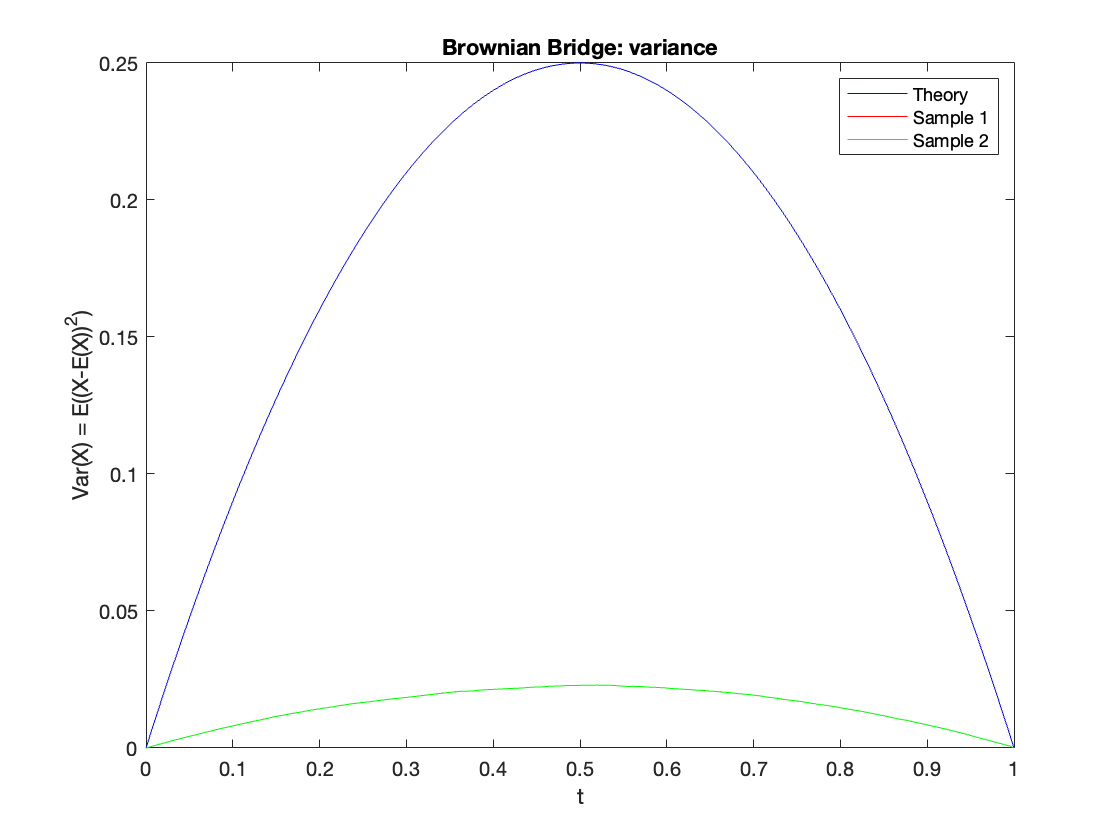

%% Variance
figure(2)
deltat = T-t;
var1 = t.*(deltat)/T ;
varX = var(X,0,2);

plot(t,var1,'b',t,var(X,0,2),'r',t,mean((X-transpose(EX)).^2,2),'g');
legend('Theory','Sample 1', 'Sample 2')
xlabel('t')
ylabel('Var(X) = E((X-E(X))^2)')
title('Brownian Bridge: variance')

## Mean absolute deviation

figure(3)
plot(t,sigma*sqrt((1-exp(-2*alpha*t))/(pi*alpha)),'r',t,sigma*sqrt(2*t/pi),'g', ...
    t,sigma/sqrt(pi*alpha)*ones(size(t)),'b',t,mean(abs(X-EX),2),'m')
legend('Theory','\sigma(2t/\pi)^{1/2}','Long-term average','Sampled','Location','SouthEast')
xlabel('t')
ylabel('E(|X-E(X)|) = (2Var(X)/pi)^{1/2}')
ylim([0 0.02])
title('Ornstein-Uhlenbeck process: mean absolute deviation')
print('-dpng','mad.png')

MAD: \sigma(2t/\pi)^{1/2} corresponds to ABM

## Probability density function at different times

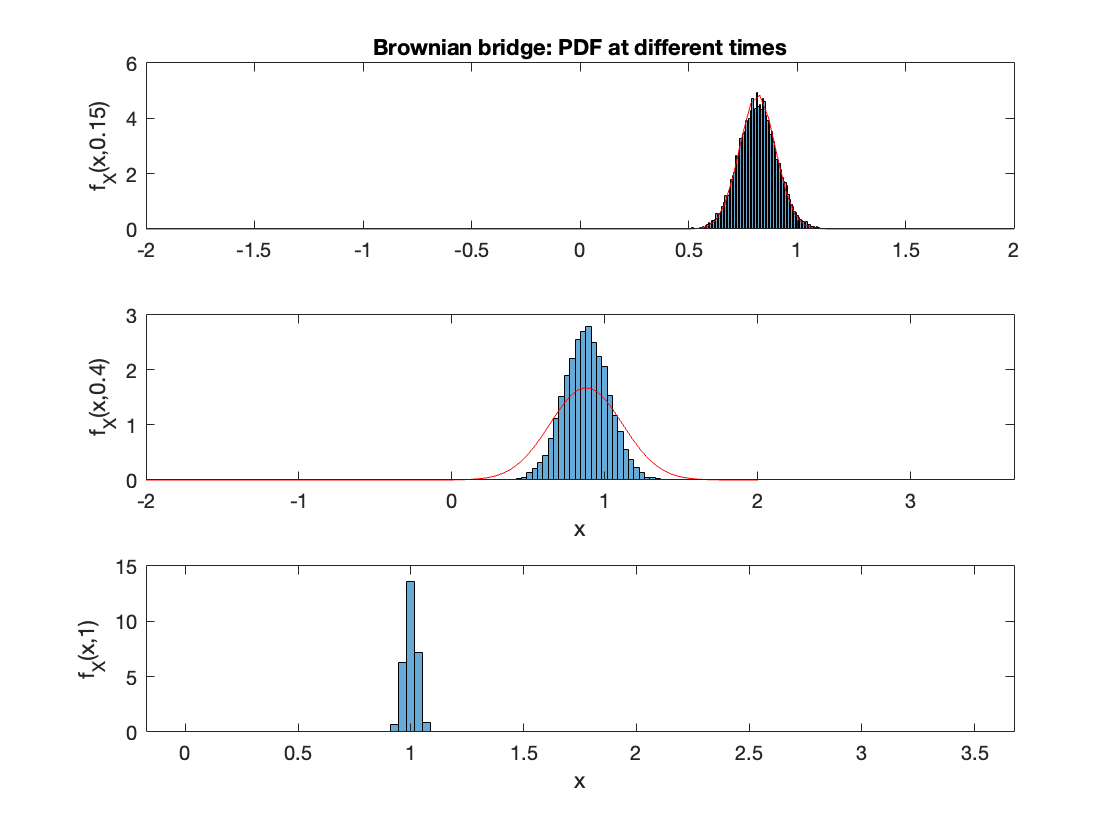

close all 
figure(4)
subplot(3,1,1)
histogram(X(20,:),100,'normalization','pdf');
% [h,x] = hist(X(20,:),100);
% h = h/(sum(h)*(x(2)-x(1)));
% bar(x,h)
hold on
grid = linspace(-2,2,100);
theo = pdf('Normal',grid,EX(19),var1(19));
plot(grid, theo,'r')
ylabel('f_X(x,0.15)')
title('Brownian bridge: PDF at different times')

subplot(3,1,2)
histogram(X(80,:),0:0.035:3.5,'normalization','pdf');
% [h,x] = hist(X(80,:),100);
% h = h/(sum(h)*(x(2)-x(1)));
% bar(x,h)
hold on
grid = linspace(-2,2,100);
theo = pdf('Normal',grid,EX(79),var1(79));
plot(grid, theo,'r')
xlabel('x')
ylabel('f_X(x,0.4)')

subplot(3,1,3)
histogram(X(end-1,:),0:0.035:3.5,'normalization','pdf');
%[h,x] = hist(X(end-1,:),100);
%h = h/(sum(h)*(x(2)-x(1)));
%bar(x,h)
hold on
grid = linspace(-2,2,300);
theo = pdf('Normal',grid,EX(end-1),var1(end-1));
xlabel('x')
ylabel('f_X(x,1)')
print('-dpng','gbpdensities.png')

## Autocovariance

=> makes only sense for quasi-stationary processes 

C = zeros(2*nsteps+1,npaths); % symmetric around zero, hence only plot one side 
for j = 1:npaths % autocovariance of each of the paths, how to vectorize??? 
    C(:,j) = xcorr(X(:,j)-EX,'unbiased');
end

Unable to perform assignment because the size of the left side is 401-by-1 and the size of the right side is 401-by-40401.

C = mean(C,2);
figure(5)
plot(t,C(nsteps+1:end),'b',t,mean(var(X,0,2))*ones(size(t)),'c')
xlabel('\tau')
ylabel('C(\tau)')
legend('Theory','Sampled','Var for infinite t','Average sampled Var','Location','East')
title('Ornstein-Uhlenbeck process: autocovariance')
print('-dpng','ouautocov.png')

## Autocorrelation

figure(6)
plot(t,exp(-alpha*t),'r',t,C(nsteps+1:end)/C(nsteps+1),'b') % devided by the value at 1 (= the central value)!!!
xlabel('\tau') 
ylabel('c(\tau)')
legend('Theory','Sampled')
title('Ornstein-Uhlenbeck process: autocorrelation')
print('-dpng','ouautocorr.png')